# DSZOB, cvičenie 3.

## **Zadanie:**

## **Úloha 1 **

Vygenerujte si nasledujúce signály podľa predchádzajúcich cvičení:

- jednoduchý signál

- zložený signál (z troch jednoduchých signálov)

- jednoduchý signál so zníženou vzorkovacou frekvenciou s porušením Nyquistovho teorému

Pre vytvorené signály:

- Z daných signálov vyberte vhodnú vzorku 512 hodnôt, vypočítajte a vizualizujte Diskrétnu Fourierovu transformáciu podľa definície.

- Následne vypočítajte a vizualizujte príslušnú inverznú Fourierovu transformáciu. Aký je výstup? 

- Výpočet DFT a IDFT implementujte ako samostatné funkcie. 

- Výstup DFT vizualizujte, pričom spektrálne indexy prevediete na Hz. (fftshift a druhá polovica výstupu; prepočet od 0 do Fs/2 Hz, index-1)

- K signálom pripočítajte konštantnú hodnotu  (DC komponentu). Vypočítajte DFT a vizualizujte (originál výstup a aj pomocou fftshift) . Kde je možné vo vypočítanej DFT DC komponentu identifikovať?

## Pomôcka (definícia):

- počet prvkov vo vektore

- index spektrálnych koeficientov

- index vzorku vo vstupnom vektore (číslicový signál o dĺžke N)

## Pomôcka:

- pozor na názov funkcií

- fftshift()

- stem()

- abs()

- j

**Postup vhodne dokumentuje (Code/Text bloky)!**

**Pri vizualizácií zamedzte zobrazovaniu upozornení.**

## **Riešenie:**

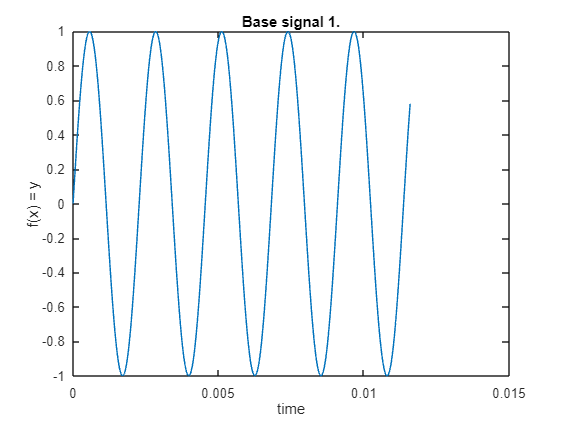

timeSamplVec = 0:1/44100:3;
len1 = 512;
xStem = -44100/2 +1:44100/len1:44100/2;                                %4.

signal1 = generateSignal(0, 3, 44100, 440, 0.8, 1);
reducedSig1 = signal1(1:512);                                          %1.
plot(timeSamplVec(1:512), reducedSig1)
title("Base signal 1.")
xlabel("time")
ylabel("f(x) = y")
xlim([0 0.015])          
ylim([-1 1])

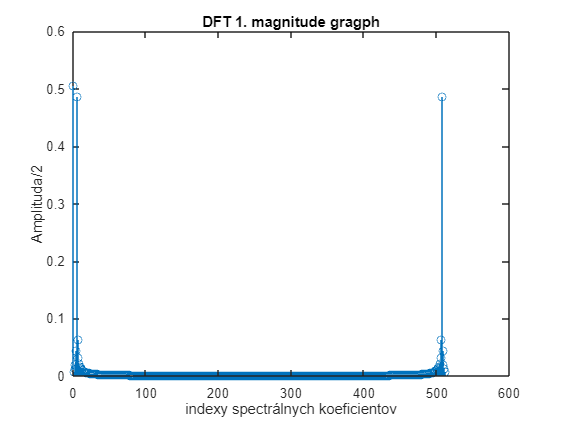

imDFS1 = calculateDFT(reducedSig1 + 0.5);                               %1., 2., 5.
dfs1 = abs(imDFS1);
stem(dfs1)
title("DFT 1. magnitude gragph")
xlabel("indexy spectrálnych koeficientov")
ylabel("Amplituda/2")

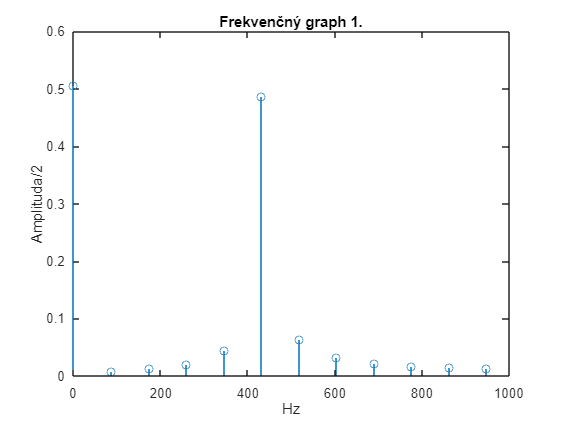

isDSF1 = fftshift(dfs1);
stem(xStem, isDSF1)
title("Frekvenčný graph 1.")
xlabel("Hz")
ylabel("Amplituda/2")
xlim([-1 1000])

imIDFS1 = calculateIDFT(imDFS1);
idfs1 = abs(imIDFS1);
plot(timeSamplVec(1:512), imIDFS1)                                    %1., 2.

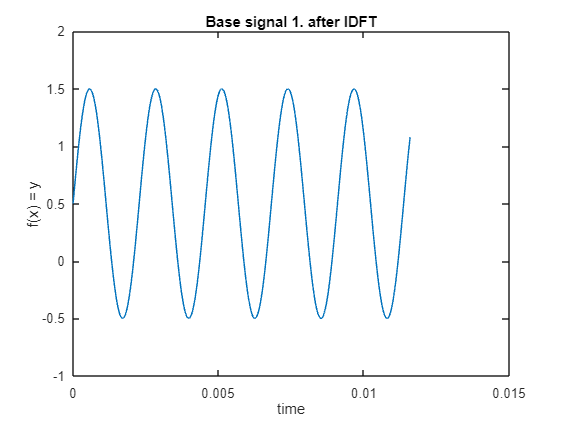

title("Base signal 1. after IDFT")
xlabel("time")
ylabel("f(x) = y")
xlim([0 0.015])
ylim([-1 2])

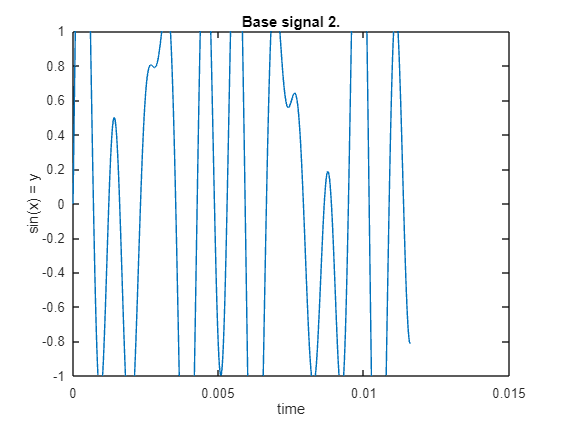


composedSignal = generateSignal(0, 3, 44100, 440, 0, 1) +  generateSignal(0, 3, 44100, 932.24, 0.2, 0.7) +  generateSignal(0, 3, 44100, 739.92, 0, 0.8);
reducedCompSig = composedSignal(1:512);                               %1.
plot(timeSamplVec(1:512), reducedCompSig)
title("Base signal 2.")
xlabel("time")
ylabel("sin(x) = y")
xlim([0 0.015])
ylim([-1 1])

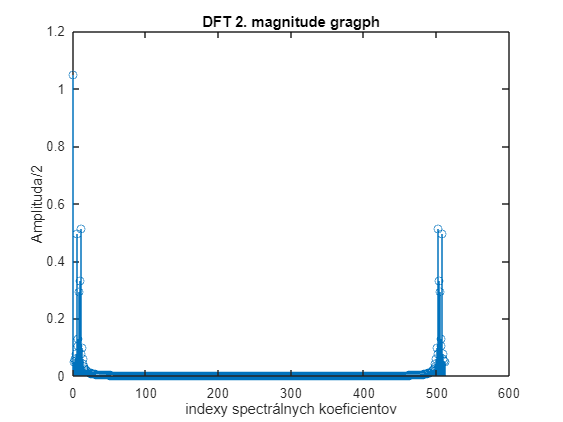

imDFS2 = calculateDFT(reducedCompSig + 1);                              %1., 2., 5.
dfs2 = abs(imDFS2);                                                     %pre dft (spectrálny graf) sú relevantné iba =>0 hodnoty, preto bola použita funkcia abs()
stem(dfs2)
title("DFT 2. magnitude gragph")
xlabel("indexy spectrálnych koeficientov")
ylabel("Amplituda/2")

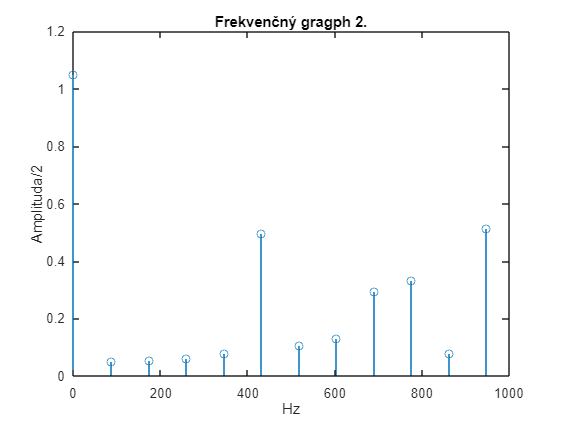

isDSF2 = fftshift(dfs2);
stem(xStem,isDSF2)
title("Frekvenčný gragph 2.")
xlabel("Hz")
ylabel("Amplituda/2")
xlim([-1 1000])

imIDFS2 = calculateIDFT(imDFS2);
idfs2 = abs(imIDFS2);
plot(timeSamplVec(1:512),imIDFS2)                                         %1., 2.

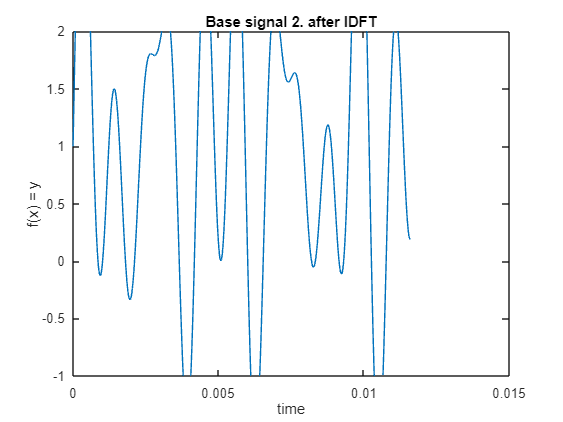

title("Base signal 2. after IDFT")
xlabel("time")
ylabel("f(x) = y")
xlim([0 0.015])                                       
ylim([-1 2])

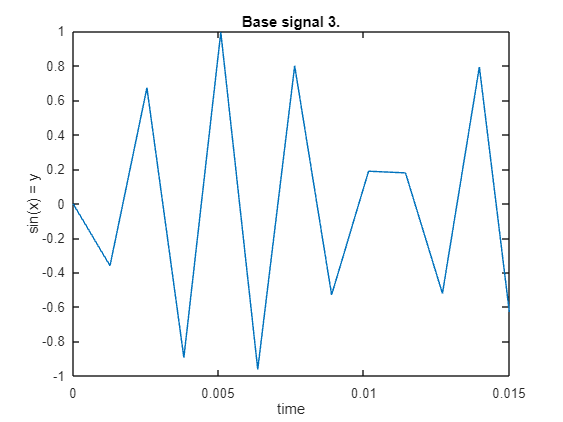


underSampledSignal = generateSignal(0, 3, 44100, 440, 0.2, 1);
divider = round(44100/(440 * 1.8));
underSampledSignal = downsample(underSampledSignal, divider);
reducedUndSampSig = underSampledSignal(1:512);                          %1.
downsampledTimeSampleVec = downsample(timeSamplVec,divider);
plot(downsampledTimeSampleVec(1:512), reducedUndSampSig)                
title("Base signal 3.")
xlabel("time")
ylabel("sin(x) = y")
xlim([0 0.015])                                       
ylim([-1 1])

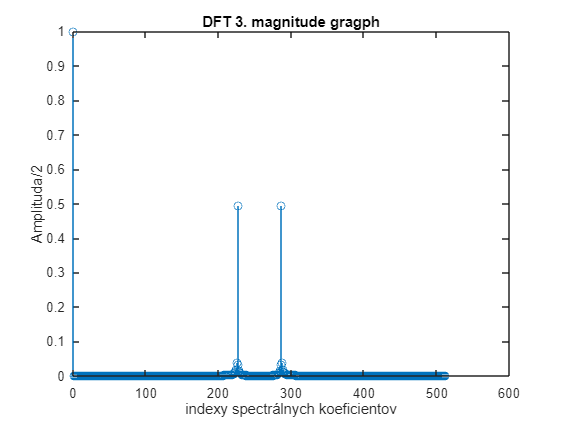

imDFS3 = calculateDFT(reducedUndSampSig + 1);                           %1., 2., 5.
dfs3 = abs(imDFS3);
stem(dfs3)
title("DFT 3. magnitude gragph")
xlabel("indexy spectrálnych koeficientov")
ylabel("Amplituda/2")

isDSF3 = fftshift(dfs3);
downSampledFS = round(44100/divider)

downSampledFS = 788

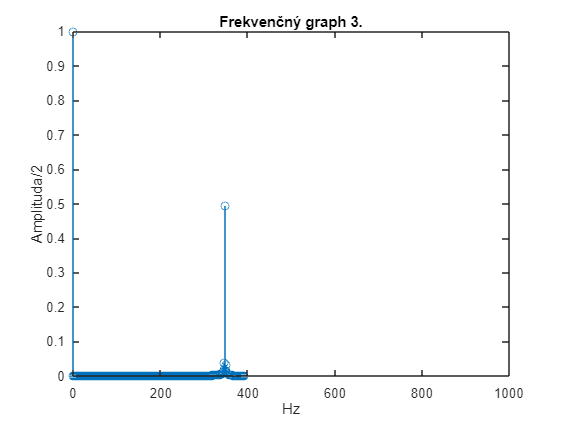

xStemForDownSampled = -downSampledFS/2 +1:downSampledFS/512:downSampledFS/2;%4.
stem(xStemForDownSampled,isDSF3)    %vzhladom na to že tento signál bol downsampnutý na FS = cca. 788, tak bolo potrebné vytvoriť nový vektor predstavujuci Hz hodnoty osi x
title("Frekvenčný graph 3.")
xlabel("Hz")
ylabel("Amplituda/2")
xlim([-1 1000])

imIDFS3 = calculateIDFT(imDFS3);
idfs3 = abs(imIDFS3);
plot(downsampledTimeSampleVec(1:512),imIDFS3)                           %1., 2.

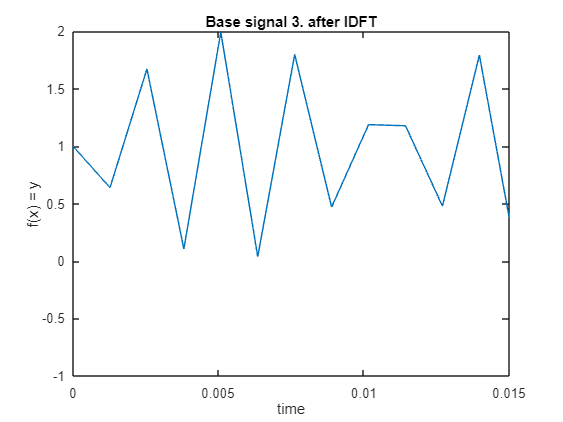

title("Base signal 3. after IDFT")
xlabel("time")
ylabel("f(x) = y")
xlim([0 0.015])                                       
ylim([-1 2])


%{ 
1. Vybratie vzorky dĺžky 512 bolo uskutočnené urezaním originálnehosignalu, na interval 0 - 512.
2. K tejto otázke. Výstup je podobný vstupnemu signalu (vstupný do dft funkcie), s tým že obsahuje i imaginárne hodnoty (nulovej hodnoty).
3. Funckcie dft a idft boli aplikované podla ich príslušných vzorcov, kedy M bolo naplnené dlžkou vstupného signalu, ktorý bol podla požiadaviek 512, tu
    je ešte jeden rozdiel od vzorcov, kedže matlab indexuje od 1, tak bolo potrebné upraviť index hodnoty x a u.
4. Všetky fazové grafy výchadzali s približne očakavanými vysledkami, tj. pre 1. fq1 = 431, fq2 = [431  (690, 776)   948] kde stredná hodnota nebola
    úplne spravné určená, a ako posledný, graf downsamplnuteho signálu, vyšiel posunuto o približne 90 Hz,
    taktiež vzhladom na porušenie nyquistovho teorému, Hz interval fázového diagramu nieje schopný zobraziť realnu hodnotu
5. K poslednej otázke. DC sa prejavuje v grafoch stem(dfs(signal)) ako hodnota f(0) a pri ich fftshift variante ako hodnota úplne v strede hodnoť (median)
%} 

## **Úloha 2 **

Vygenerujte si jednoduchý signál. Pre okienko veľkosti 512 a okienko dĺžky, ktoré nezachytí ani celú základnú periódu (je príliš krátke) vypočítajte a vizualizujte DFT. Sú výstupné spektrá zhodné? Prečo je to tak?

## **Riešenie:**

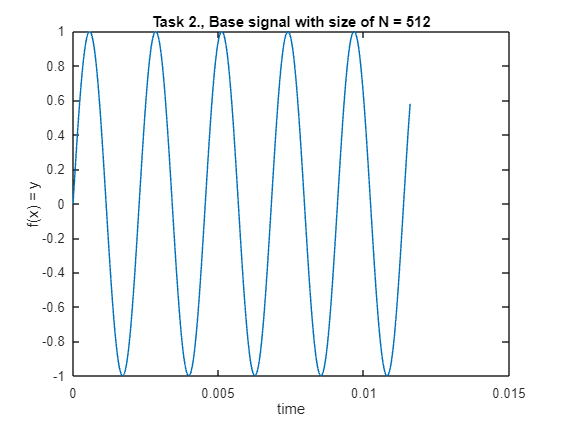


signal2 = generateSignal(0, 3, 44100, 440, 0.5, 0.8);
signal21 = signal2(1:512);
plot(timeSamplVec(1:512), signal21)
title("Task 2., Base signal with size of N = 512")
xlabel("time")
ylabel("f(x) = y")
xlim([0 0.015])                                       
ylim([-1 1])

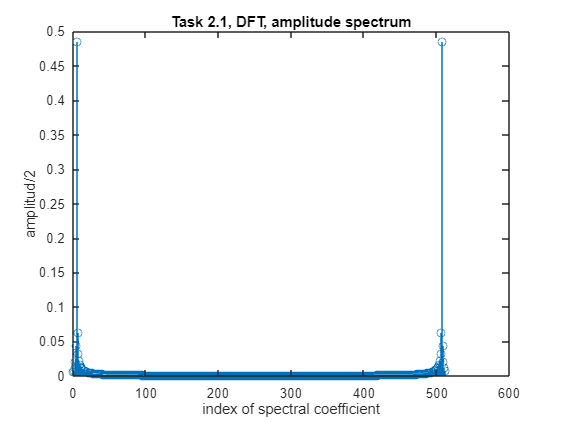


imDFT4 = calculateDFT(signal21);
dft4 = abs(imDFT4);
stem(dft4)
title("Task 2.1, DFT, amplitude spectrum")
xlabel("index of spectral coefficient")
ylabel("amplitud/2");

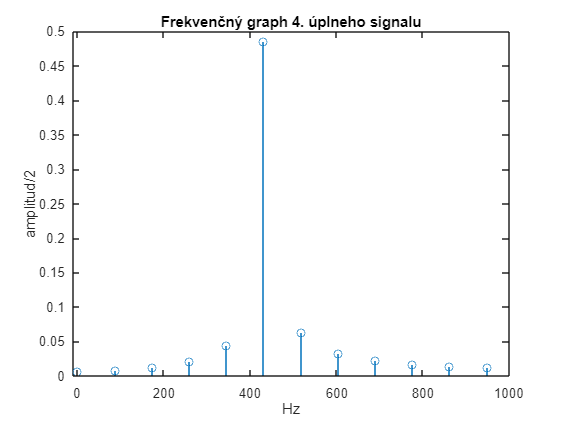

stem(xStem,fftshift(dft4))
title("Frekvenčný graph 4. úplneho signalu")
xlabel("Hz")
ylabel("amplitud/2")
xlim([-10 1000])

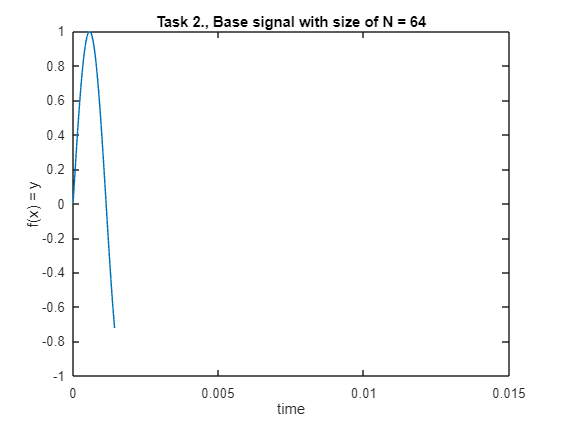


signal22 = signal2(1:64);
plot(timeSamplVec(1:64), signal22)
title("Task 2., Base signal with size of N = 64")
xlabel("time")
ylabel("f(x) = y")
xlim([0 0.015])                                       
ylim([-1 1])

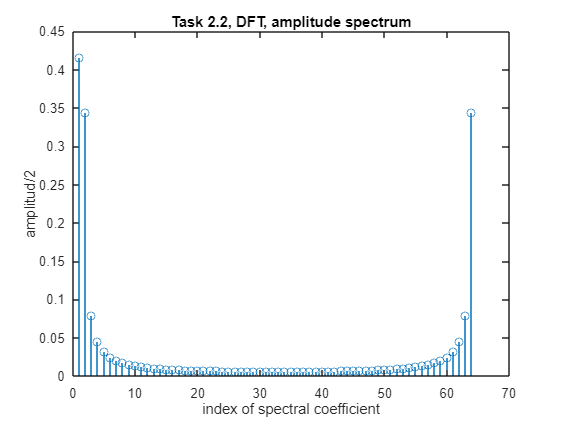

imDFT5 = calculateDFT(signal22);
dft5 = abs(imDFT5);
stem(dft5)
title("Task 2.2, DFT, amplitude spectrum")
xlabel("index of spectral coefficient")
ylabel("amplitud/2");

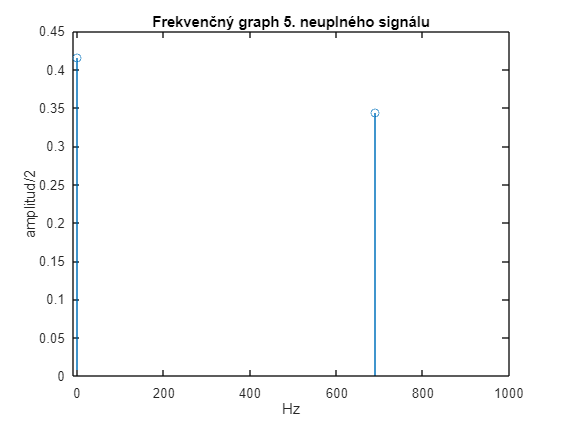

xStem2 = -22050 + 1:44100/64:22050;
stem(xStem2,fftshift(dft5))
title("Frekvenčný graph 5. neuplného signálu")
xlabel("Hz")
ylabel("amplitud/2");
xlim([-10 1000])


%{ 
X. Prosim o zrozumeítelnejsi zápis zadania, velkost != dlzka.
1. Vygenerovanie jednoducheho signalov dlzky 512 a 64 kde signál nemá celú
periodu.
2. Dft bol vypocitany, vystupné spektrá  nie su rovnaké, jednak pri
neuplnom signali sa v spektri nachádza nenulový nulty index (DC) a taktiež
najdná frekvencia nesedí (ozajsná = 440Hz a najdená cca 690Hz), taktiež
amplitudy niesu rovnaké.
%} 

## Priestor pre vaše funkcie:

function [signal] = generateSignal(min, max, defSampFreq, toneFreq, amplitudeMin, amplitudeMax)
    timeSamplVec = min:1/defSampFreq:max;
    ampl = mod(rand() + amplitudeMin, amplitudeMax);     
    signal = sin(2*pi*timeSamplVec*toneFreq) * 1;
end
%{ and %} 
function [solution] = calculateDFT(signal)
    M = length(signal);   %
    %u = count of peaks in given signal
    solution = linspace(0,1,M); % pre-filling of vector, for speeding up of the function
    for u = 1:(M)
        suma = 0;
        for x = 1:(M)
            suma = suma + signal(x)*exp(1)^(-1i*2*pi*(x-1)*(u-1)/M);
        end
        suma = suma / M;
        solution(u) = suma;
    end
end

function [solution] = calculateIDFT(spectralVector)
    M = length(spectralVector);   %
    %u = count of peaks in given signal
    solution = linspace(0,1,M); % pre-filling of vector, for speeding up of the function
    for x = 1:(M)
        suma = 0;
        for u = 1:(M)
            suma = suma + spectralVector(u)*exp(1)^(1i*2*pi*(x-1)*(u-1)/M);
        end
        solution(x) = suma;
    end
end
%{ and %}